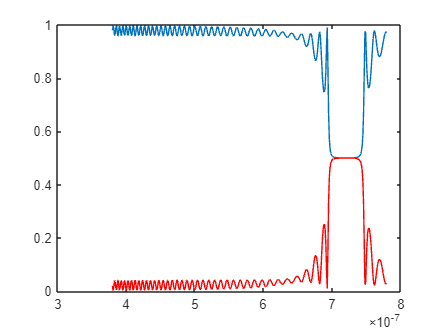

      n_e = 1.65;      
      n_o = 1.55;   
      n_s = 1.3;   
      p = 450 *10^(-9);   
            
            
            
            d = 10 * (10^(-6)); % CLC thickness
N = 1000;           % number of CLC waveplates
t = d/N;            % thickness of each CLC waveplates

 % pitch 
lamda_c = ((n_o+n_e)/2) * p; % central wavelength of PBGs

e_0 = 8.85*(10^(-12)); % vaccum permittivity
u = 4*pi * (10^(-7));  % vaccum magnetic permeability 
c_light = 3 *(10^(8)); % speed of light in vaccum
l = d/p;               % thickness (depth) per pitch

%---------------------------parameters------------------------------------------------------
%%
%---------------------------preparing memory space for data plotting-----------------------
% wavelength range : 380nm ~ 780nm (delta 400nm)

axis_x = zeros(1,401);
axis_y = zeros(1,401); % memory space for plotting transmittance : delta 400nm
n=1;
m=1;                   % index number for arrangements of transmittance 

axis_a = zeros(1,401);
axis_b = zeros(1,401); % memory space for plotting reflectance : delta 400nm
n_n=1;
m_m=1;                 % index number for arrangements of reflectance

%---------------------------preparing memory space for data plotting-----------------------
%%
% Assumption for CLCs : wave vector k only propagates in z-direction
%%
% "for" loop for wavelength "lamda", 380nm ~ 780nm
% increment unit: 1nm

for lamda = 380*10^(-9) : 10^(-9) : 780 * 10^(-9) 

    omega = 2*pi*c_light/lamda;  % angular frequency 
           % wavelength of monochromatic light in vaccuum
    k_0 = 2*pi/ lamda;         % wave number


    %----------------wave vectors 1~4 for substrates ------------------

    k_1_0 = [0 0 n_s * k_0];      
    k_2_0 = [0 0 -n_s * k_0];
    k_3_0 = [0 0 n_s * k_0];
    k_4_0 = [0 0 -n_s * k_0];

    %----------------wave vectors 1~4 for substrates ------------------

    %----------------polarization vectors for substrates---------------

    p_1_1 = cross(k_1_0,[1 0 0]);                                        
    p_1_0 = p_1_1 / (sqrt(p_1_1(1,1)^2 + p_1_1(1,2)^2 + p_1_1(1,3)^2));    
    
    p_1_2 = cross(k_2_0,[1 0 0]);
    p_2_0 = p_1_2 / (sqrt(p_1_2(1,1)^2 + p_1_2(1,2)^2 + p_1_2(1,3)^2));
    
    p_1_3 = cross(k_3_0,p_1_0);
    p_3_0 = p_1_3 / (sqrt(p_1_3(1,1)^2 + p_1_3(1,2)^2 + p_1_3(1,3)^2));
    
    p_1_4 = cross(k_4_0,p_2_0);
    p_4_0 = p_1_4 / (sqrt(p_1_4(1,1)^2 + p_1_4(1,2)^2 + p_1_4(1,3)^2));

    %----------------polarization vectors for substrates---------------

    %----------------polarization vectors of magnetic field for substrates

    q_1_0 = cross(k_1_0/(omega*u),p_1_0);
    q_2_0 = cross(k_2_0/(omega*u),p_2_0);
    q_3_0 = cross(k_3_0/(omega*u),p_3_0);
    q_4_0 = cross(k_4_0/(omega*u),p_4_0);

    %----------------polarization vectors of magnetic field for substrates

    %----------------Components of 4x4 Matrix for substrates--------------


    D_0 =  [p_1_0(1,1) p_2_0(1,1) p_3_0(1,1) p_4_0(1,1); p_1_0(1,2) p_2_0(1,2) p_3_0(1,2) p_4_0(1,2); q_1_0(1,1) q_2_0(1,1) q_3_0(1,1) q_4_0(1,1); q_1_0(1,2) q_2_0(1,2) q_3_0(1,2) q_4_0(1,2)]; %Dynamical matrix D

    P_0 = diag([exp(1i*n_s*k_0*t) exp(1i*(-n_s)*k_0*t) exp(1i*n_s*k_0*t) exp(1i*(-n_s)*k_0*t)]); % Propagation matrix P
   
    %----------------Components of 4x4 Matrix for substrates--------------

    M = diag([1 1 1 1]);
    
    % "for" loop for rotation angle of CLC molcules "theta", 380nm ~ 780nm

    for w = 1:N
        theta = 2*pi*w*l/N;
        c = [cos(theta), sin(theta), 0]; % molecule director

    %-----------wave vector propagating in CLCs-----------------------
  
    g_1 = sqrt(omega^2*u*e_0*n_o^2);
    g_2 = -sqrt(omega^2*u*e_0*n_o^2);
    g_3 = sqrt(omega^2*u*e_0*n_e^2);
    g_4 = -sqrt(omega^2*u*e_0*n_e^2);
    
    k_1 = [0 0 g_1];
    k_2 = [0 0 g_2];
    k_3 = [0 0 g_3];
    k_4 = [0 0 g_4];
    
    %-----------wave vector propagating in CLCs-----------------------
    
    %----------------polarization vectors ----------------------------
    p_11 = cross(k_1,c);
    p_1 = p_11 / (sqrt(p_11(1,1)^2 + p_11(1,2)^2 + p_11(1,3)^2));

    p_22 = cross(k_2,c);
    p_2 = p_22 / (sqrt(p_22(1,1)^2 + p_22(1,2)^2 + p_22(1,3)^2));

    p_33 = cross(p_1,k_3);
    p_3 = p_33 / (sqrt(p_33(1,1)^2 + p_33(1,2)^2 + p_33(1,3)^2)); 

    p_44 = cross(p_2,k_4);
    p_4 = p_44 / (sqrt(p_44(1,1)^2 + p_44(1,2)^2 + p_44(1,3)^2));
    
    %----------------polarization vectors ----------------------------

    %----------------polarization vectors of magnetic field-----------
    q_1 = cross(k_1/(omega*u),p_1);
    q_2 = cross(k_2/(omega*u),p_2) ;
    q_3 = cross(k_3/(omega*u),p_3) ;
    q_4 = cross(k_4/(omega*u),p_4);

    %----------------polarization vectors of magnetic field-----------

    %----------------Components of 4x4 Matrix---------------------------
    D = [p_1(1,1) p_2(1,1) p_3(1,1) p_4(1,1); p_1(1,2) p_2(1,2) p_3(1,2) p_4(1,2); q_1(1,1) q_2(1,1) q_3(1,1) q_4(1,1); q_1(1,2) q_2(1,2) q_3(1,2) q_4(1,2)];

    P = diag([exp(1i*g_1*t) exp(1i*g_2*t) exp(1i*g_3*t) exp(1i*g_4*t)]);
    %----------------Components of 4x4 Matrix---------------------------
    

     
    M = M * D*P/D;
    end


M = D_0\ M * D_0; % 4X4 Matrix



%%
%----------------------------------- Calculation for Transmittance------------------------------

T_1 = abs(M(1,1)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
T_2 = abs(M(3,3)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
T_3 = abs(M(1,3)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);
T_4 = abs(M(3,1)^2 / (M(1,1)*M(3,3) - M(1,3)*M(3,1))^2);

T = (T_1+T_2+T_3+T_4) /2;

%----------------------------------- Calculation for Transmittance------------------------------

R = 1-T; % Reflectance

%----------------------------------- Plotting transmittance & reflectance-----------------------

axis_x(1,n) = lamda;
axis_y(1,m) = T;
axis_a(1,n_n) = lamda;
axis_b(1,m_m) = R;
n = n+1;
m = m+1;
n_n = n_n+1;
m_m = m_m+1;

end

plot(axis_x, axis_y,axis_a,axis_b,"red");   % Transmittance (x,y) / Reflectance (a,b)


%----------------------------------- Plotting transmittance & reflectance-----------------------

 
